# MCSB Bootcamp - Some Matlab notes

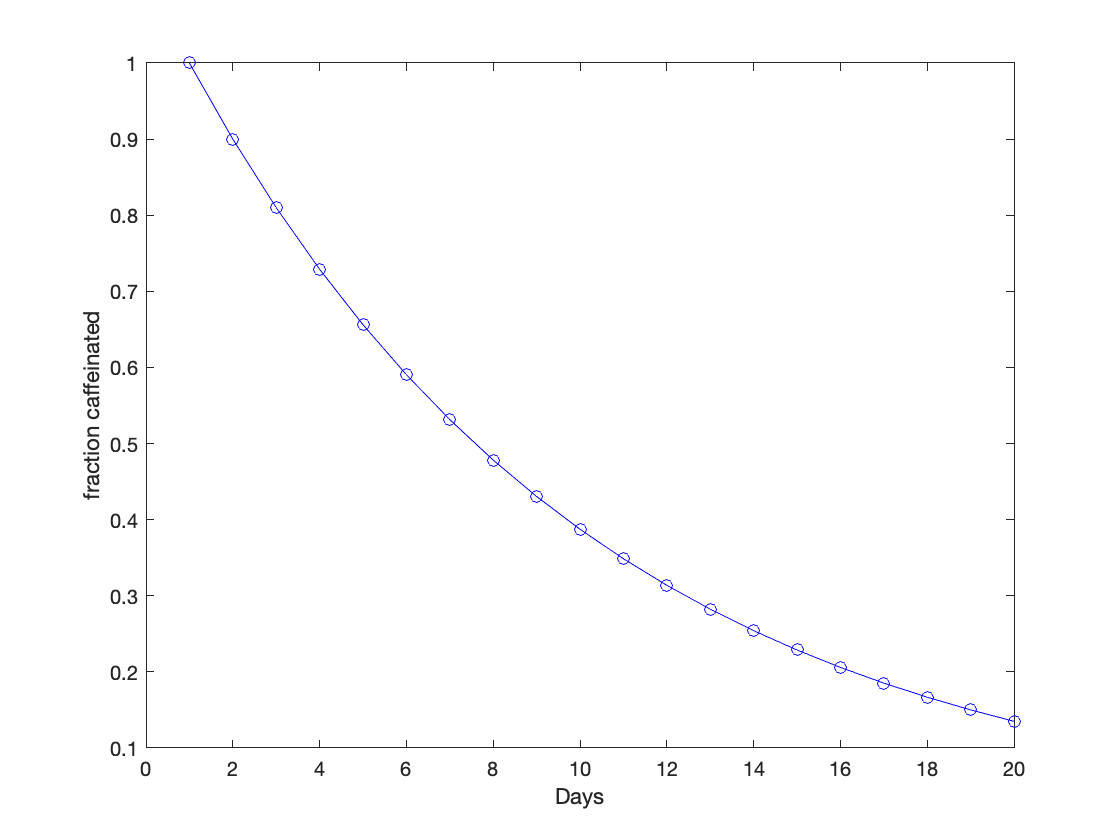

% How much caffeine is there in the jar?

% n - number of days
% x - fraction of caffeinated 

nMax = 20; % max number of days to simulate

N = 10; % number of scoops in each jar
x = zeros(1,nMax); % fraction caffeinated
x(1) = 1.0; % initial fraction caffeinated

for n=2:nMax
    
    x(n) = (1-1/N) * x(n-1);
    
end % finished loop through days

figure;
plot(x,'-ob'); 
ylabel('fraction caffeinated')
xlabel('Days')

There are many plot styles.

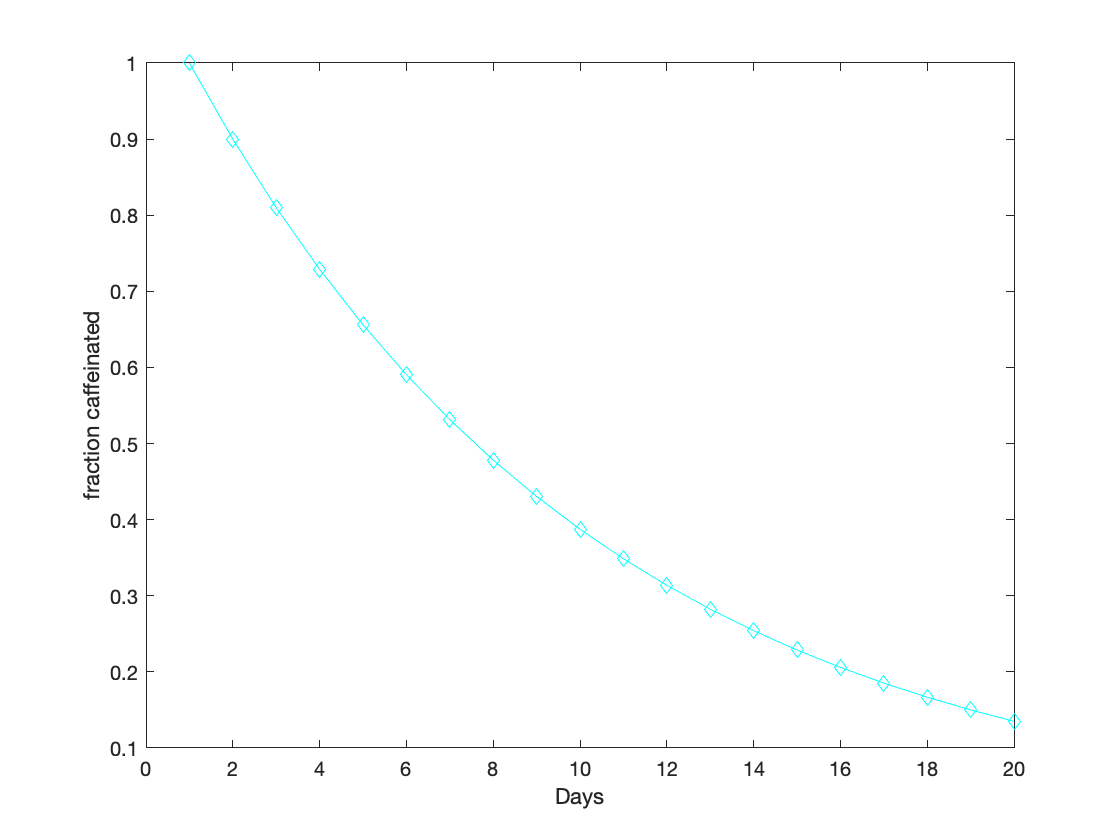

figure;
plot(x,'-dc'); 
ylabel('fraction caffeinated')
xlabel('Days')

The key data structure in Matlab is the **matrix**.

x

x =     1.0000    0.9000    0.8100    0.7290    0.6561    0.5905    0.5314    0.4783    0.4305    0.3874    0.3487    0.3138    0.2824    0.2542    0.2288    0.2059    0.1853    0.1668    0.1501    0.1351


y = [1 2 3 4 27] % defines a matrix explicitly

y =      1     2     3     4    27


ones(1,20) % a matrix of 1's!

ans =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


ones(20,1)

ans =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


zeros(1,20)

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


rand(1,5) %uniform ramdomly distributed numbers between 0 and 1, multiply for numbers between others

ans =     0.8147    0.9058    0.1270    0.9134    0.6324


1:10

ans =      1     2     3     4     5     6     7     8     9    10


1:-1:-10 %middle number describes space between entries

ans =      1     0    -1    -2    -3    -4    -5    -6    -7    -8    -9   -10


linspace(3,7,10) % linearly spaced entries in a matrix

ans =     3.0000    3.4444    3.8889    4.3333    4.7778    5.2222    5.6667    6.1111    6.5556    7.0000


The semicolon ; is used to suppress output.

x = rand(1,10);
display('Hello world!');

Hello world!


x = rand(1,10) % no semicolon

x =     0.1419    0.4218    0.9157    0.7922    0.9595    0.6557    0.0357    0.8491    0.9340    0.6787


A key feature of Matlab is that many operations are performed on matrices. For example, the **diff() ** operator takes the difference between each neighboring element of a matrix.

diff([1 2 3 4 27])

ans =      1     1     1    23


The flow control operations like **if, if-else, for, while** are similar to other languages.

z = 0.7;
if (z < 0.5)
        display('z is small'); %whitespace is not recognized by matlab --> only used for readability 
else 
    display('z is big'); 
end

z is big


for i=1:2:10
    x(i) = i^2;
end

display(x)

x =     1.0000    0.4218    9.0000    0.7922   25.0000    0.6557   49.0000    0.8491   81.0000    0.6787


Operations on the elements of a matrix require a period "." . 

x = 1:10;
y = x.^2;

display(y)

y =      1     4     9    16    25    36    49    64    81   100
